# Example - how make a plot with different colormaps

**Author**: Abakumov Ivan

Freie Universität Berlin

**Publication date**: 22nd September 2017

**E-mail**: [abakumov_ivan@mail.ru](mailto:abakumov_ivan@mail.ru)

## Add MLIB library

clear; close all; clc;
mlibfolder = '/home/ivan/Desktop/MLIB';
path(path, mlibfolder);
add_mlib_path;

## Introduction

This script is based on the original code of 

John Iversen

john_iversen@post.harvard.edu

[https://de.mathworks.com/matlabcentral/fileexchange/7943-freezecolors-unfreezecolors](https://de.mathworks.com/matlabcentral/fileexchange/7943-freezecolors-unfreezecolors)

and Carlos Adrian Vargas Aguilera

[http://www.mathworks.com/matlabcentral/fileexchange/24371](http://www.mathworks.com/matlabcentral/fileexchange/24371)

## Example 1:

Let us plot a figure using subplot with 'hot' colormap.

figure(1)
subplot(1,2,1)
imagesc(peaks); 
colormap hot; 
title('hot colormap'); 
h1=colorbar;

If we plot the second subplot with the jet colormap, the plot will change appearance. 

This is normal Matlab behavior.

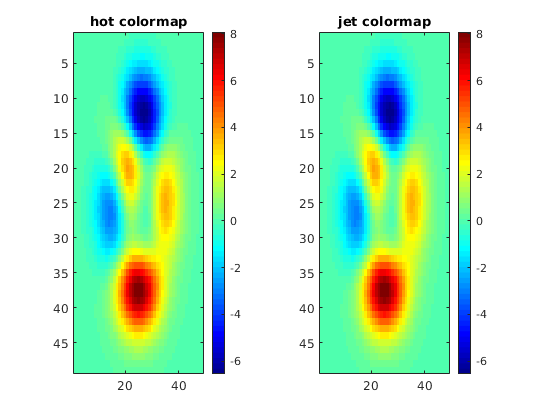

subplot(1,2,2)
imagesc(peaks); 
colormap jet
title('jet colormap')
h2=colorbar;

The two plots should appear identical.

## Example 2:

**freezeColors **allows multiple colormaps to be used per figure

**cbfreeze** allows to freeze the colorbar

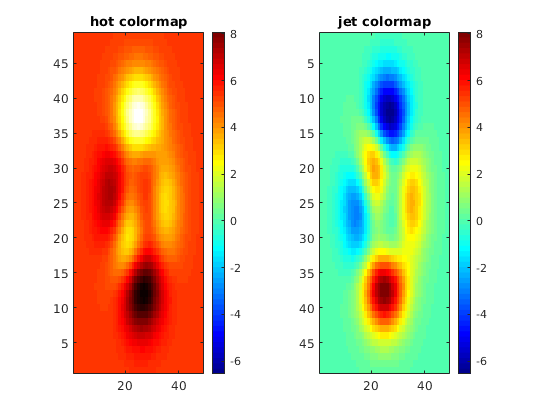

figure(2)
clf
subplot(1,2,1)
imagesc(peaks); 
colormap hot; 
title('hot colormap');
freezeColors; 
h1=colorbar;
try
    cbfreeze(h1)
catch
    freezeColors(h1)
end

subplot(1,2,2)
imagesc(peaks); 
colormap jet
title('jet colormap')
freezeColors; 
h2=colorbar;

try
    cbfreeze(h2)
catch
    freezeColors(h2)
end